## VJM model of KUKA_iiwa robot manipulator:

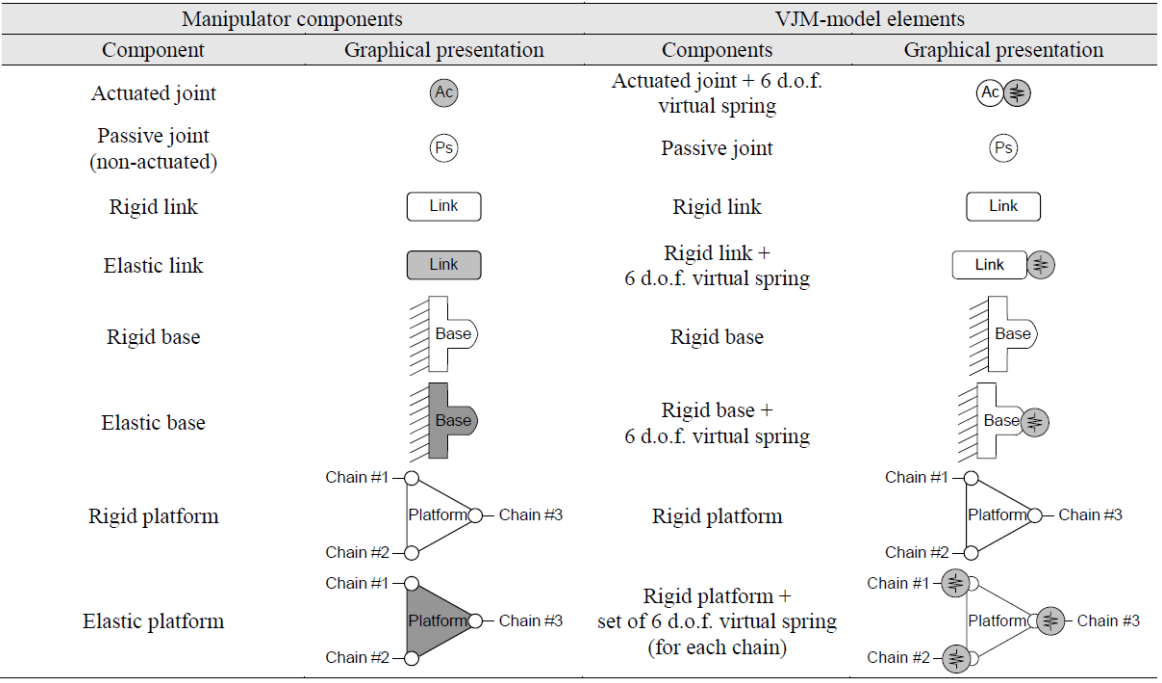

## 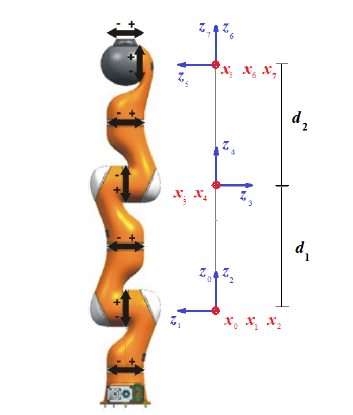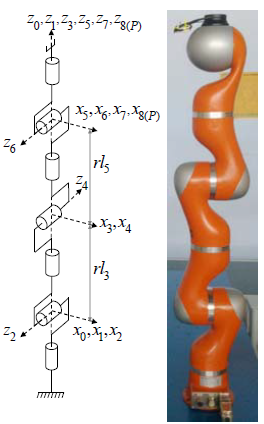

## **The extended model of the KUKA manipulator:**


$$
$T_{ext}= T_{base}\cdot R_{z,q_{1}}\cdot R_{z,\theta_{1}} \cdot T_{z,d_{1}} \cdot H_{3D,\theta_{7}}\cdot R_{x,q_{2}}\cdot R_{x,\theta_{8}} \cdot T_{z,d_{2}} \cdot H_{3D,\theta_{14}} \cdot R_{z,q_{3}}\cdot R_{z,\theta_{15}}\cdot T_{z,d_{3}} \cdot H_{3D,\theta_{21}} \cdot R_{x,q_{4}}\cdot R_{x,\theta_{22}} \cdot T_{z,d_{4}} \cdot H_{3D,\theta_{28}} \cdot R_{z,q_{5}}\cdot R_{z,\theta_{29}} \cdot T_{z,d_{5}} \cdot H_{3D,\theta_{35}} \cdot R_{x,q_{6}}\cdot R_{x,\theta_{36}} \cdot T_{z,d_{6}} \cdot H_{3D,\theta_{42}} \cdot R_{z,q_{7}}\cdot R_{z,\theta_{43}}\cdot T_{Tool}$$$


with: $H_{3D}= T_x \cdot T_y \cdot T_z \cdot R_x \cdot R_y \cdot R_z $

clear all, clc
Tbase = eye(4);
Ttool = eye(4);

% Actuator stiff 1
k0 = 1e6; 

%LINK1
%material and shape parameters
E = 70 *10e9; %Young's modulus
G = 25.5*10e9; %shear modulus
robot.d(1) = 10*10e-3;
robot.L(1) = 0.21;

%for cylinder
S = pi*robot.d(1)^2/4;
Iy = pi*robot.d(1)^4/64;
Iz = pi*robot.d(1)^4/64;
J = Iy + Iz;


k1 = [E*S/robot.L(1) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(1)^3  0                 0           0                 6*E*Iy/robot.L(1)^2;
    0           0                  12*E*Iy/robot.L(1)^3 0           -6*E*Iy/robot.L(1)^2 0;
    0           0                  0                 G*J/robot.L(1) 0                 0;
    0           0                  -6*E*Iy/robot.L(1)^2 0           4*E*Iy/robot.L(1)      0;
    0           6*E*Iy/robot.L(1)^2   0                 0           0                 4*E*Iz/robot.L(1)];


% Actuator stiff 2
k2 = 1e6; 

%LINK2
%material and shape parameters
robot.d(2) = 10*10e-3;
robot.L(2) = 0.21;


k3 = [E*S/robot.L(2) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(2)^3  0                 0           0                 6*E*Iy/robot.L(2)^2;
    0           0                  12*E*Iy/robot.L(2)^3 0           -6*E*Iy/robot.L(2)^2 0;
    0           0                  0                 G*J/robot.L(2) 0                 0;
    0           0                  -6*E*Iy/robot.L(2)^2 0           4*E*Iy/robot.L(2)      0;
    0           6*E*Iy/robot.L(2)^2   0                 0           0                 4*E*Iz/robot.L(2)];


% Actuator stiff 3
k4 = 1e6; 

%LINK3
%material and shape parameters
robot.d(3) = 10*10e-3;
robot.L(3) = 0.21;

k5 = [E*S/robot.L(3) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(3)^3  0                 0           0                 6*E*Iy/robot.L(3)^2;
    0           0                  12*E*Iy/robot.L(3)^3 0           -6*E*Iy/robot.L(3)^2 0;
    0           0                  0                 G*J/robot.L(3) 0                 0;
    0           0                  -6*E*Iy/robot.L(3)^2 0           4*E*Iy/robot.L(3)      0;
    0           6*E*Iy/robot.L(3)^2   0                 0           0                 4*E*Iz/robot.L(3)];

% Actuator stiff 4
k6 = 1e6; 

%LINK4
%material and shape parameters
robot.d(4) = 10*10e-3;
robot.L(4) = 0.2;

k7 = [E*S/robot.L(4) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(4)^3  0                 0           0                 6*E*Iy/robot.L(4)^2;
    0           0                  12*E*Iy/robot.L(4)^3 0           -6*E*Iy/robot.L(4)^2 0;
    0           0                  0                 G*J/robot.L(4) 0                 0;
    0           0                  -6*E*Iy/robot.L(4)^2 0           4*E*Iy/robot.L(4)      0;
    0           6*E*Iy/robot.L(4)^2   0                 0           0                 4*E*Iz/robot.L(4)];

% Actuator stiff 5
k8 = 1e6; 

%LINK5
%material and shape parameters
robot.d(5) = 10*10e-3;
robot.L(5) = 0.2;

k9 = [E*S/robot.L(5) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(5)^3  0                 0           0                 6*E*Iy/robot.L(5)^2;
    0           0                  12*E*Iy/robot.L(5)^3 0           -6*E*Iy/robot.L(5)^2 0;
    0           0                  0                 G*J/robot.L(5) 0                 0;
    0           0                  -6*E*Iy/robot.L(5)^2 0           4*E*Iy/robot.L(5)      0;
    0           6*E*Iy/robot.L(5)^2   0                 0           0                 4*E*Iz/robot.L(5)];

% Actuator stiff 6
k10 = 1e6; 

%LINK6
%material and shape parameters
robot.d(6) = 10*10e-3;
robot.L(6) = 0.126;

k11 = [E*S/robot.L(6) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(6)^3  0                 0           0                 6*E*Iy/robot.L(6)^2;
    0           0                  12*E*Iy/robot.L(6)^3 0           -6*E*Iy/robot.L(6)^2 0;
    0           0                  0                 G*J/robot.L(6) 0                 0;
    0           0                  -6*E*Iy/robot.L(6)^2 0           4*E*Iy/robot.L(6)      0;
    0           6*E*Iy/robot.L(6)^2   0                 0           0                 4*E*Iz/robot.L(6)];

% Actuator stiff 7
k12 = 1e6; 




% K theta matrixshow
Kt = [k0 zeros(1,42)
    zeros(6,1) k1 zeros(6,36)
    zeros(1,1) zeros(1,6) k2 zeros(1,35)
    zeros(6,1) zeros(6,6) zeros(6,1) k3 zeros(6,29)
    zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) k4 zeros(1,28)
    zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) k5 zeros(6,22)
    zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) k6 zeros(1,21)
    zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) k7 zeros(6,15)
    zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6)  k8 zeros(1,14)
    zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) k9 zeros(6,8)
    zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) k10 zeros(1,7)
    zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) zeros(6,6) zeros(6,1) k11 zeros(6,1)
    zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) zeros(1,1) zeros(1,6) k12];
Kt

Kt = 	1.0e+10 *

    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    2.6180         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.4452         0         0         0    0.0467         0         0         0         0         0 

q= [0,0,0,0,0,0,0]

q =      0     0     0     0     0     0     0


t= zeros(1, 43)

t =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


d =[robot.L(1), robot.L(2), robot.L(3), robot.L(4), robot.L(5), robot.L(6)]

d =     0.2100    0.2100    0.2100    0.2000    0.2000    0.1260


Jth= Jt(Tbase,Ttool,q,t,d)

Jth =          0    1.0000         0         0         0    0.9460         0         0    1.0000         0         0         0    0.7360         0         0    1.0000         0         0         0    0.5260         0         0    1.0000         0         0         0    0.3260         0         0    1.0000         0         0         0    0.1260         0         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0   -0.9460         0         0   -0.9460         0    1.0000         0   -0.7360         0         0         0         0    1.0000         0   -0.5260         0         0   -0.5260         0    1.0000         0   -0.3260         0         0         0         0    1.0000         0   -0.1260         0         0   -0.1260         0    1.0000         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0  

Kc0=inv(Jth*inv(Kt)*Jth')

Kc0 = 	1.0e+08 *

    0.2935         0   -0.2232         0   -0.1187         0
         0    0.0257         0    0.0135         0    0.0002
   -0.2232         0    8.7567         0   -0.7572         0
         0    0.0135         0    0.0100         0    0.0001
   -0.1187         0   -0.7572         0    0.1613         0
         0    0.0002         0    0.0001         0    0.0023


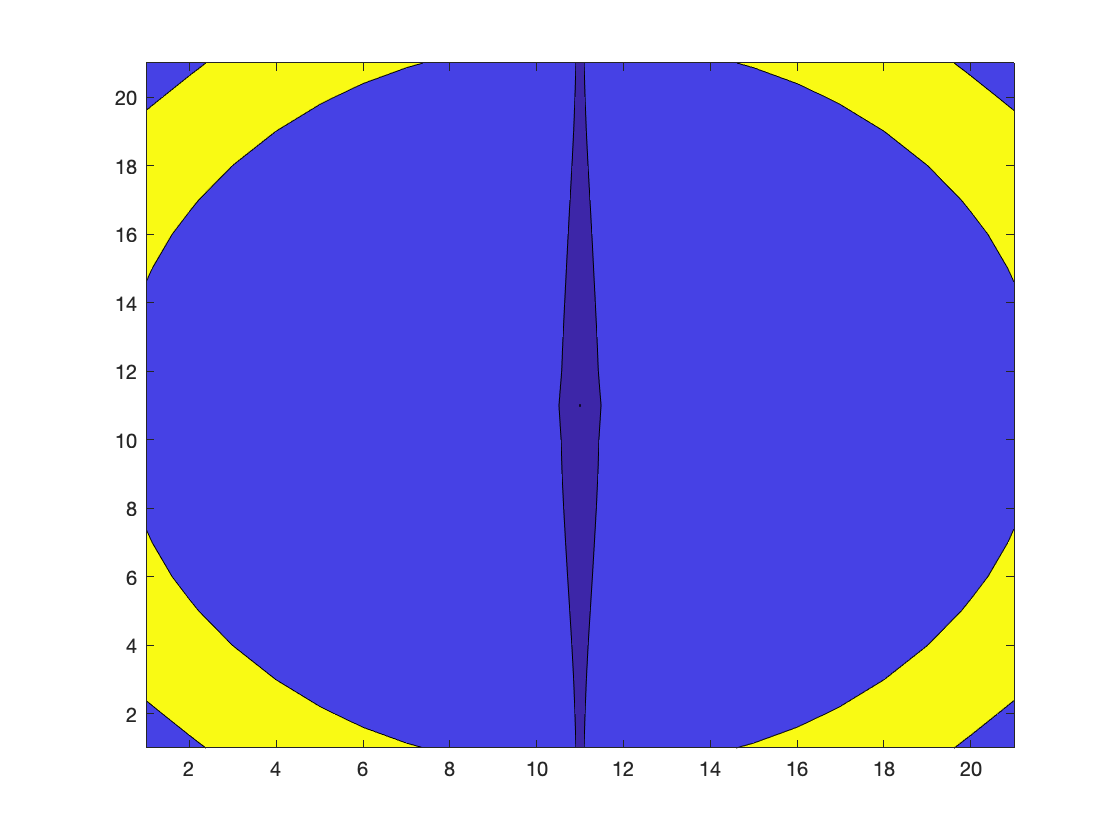

F = [0;0;1000;0;0;0];
showDeflection(F, 'VJM')

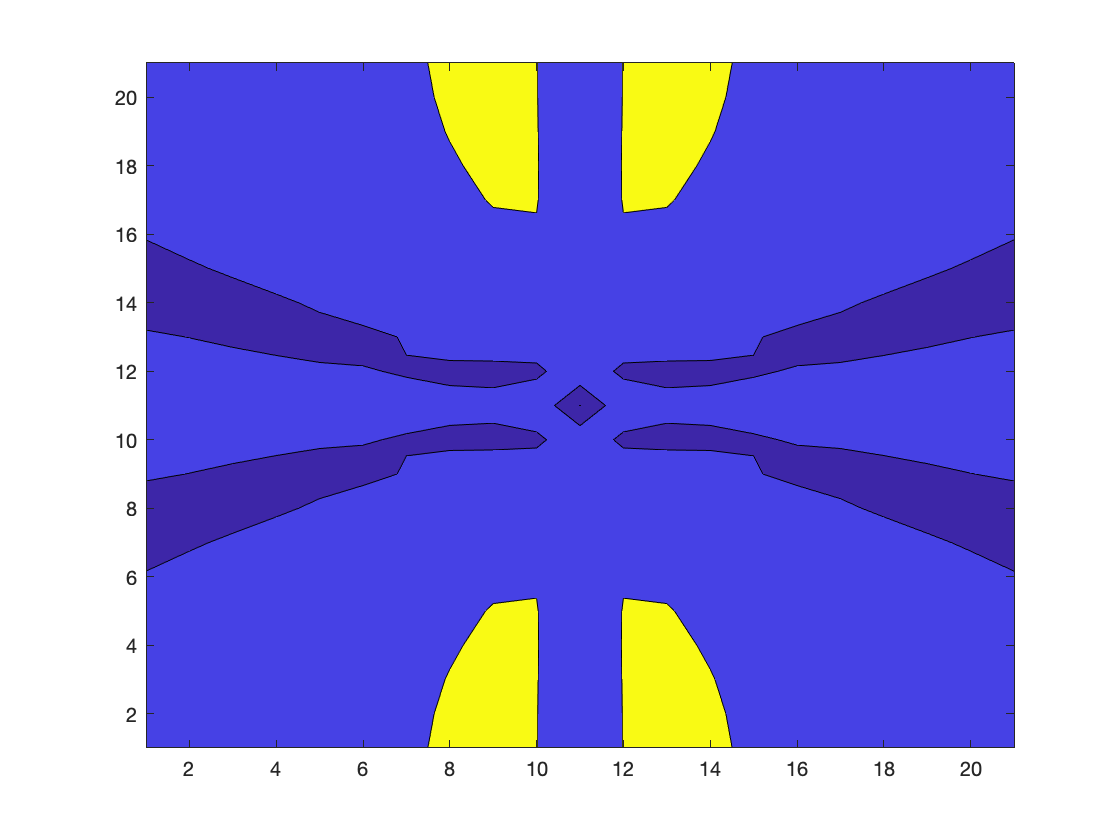

showDeflection(F, 'MSA')